# Tune Tracking Filter Using Tuning Data Generated from Tracking Scenario

Instantiate the filter with the first detection - give it a reasonable starting point.

filter = initctekf(initialDetection);

Create a `trackingFilterTuner` object and set its `Display` property to `"Plot"`.

tuner = trackingFilterTuner('Display',"Plot",'Cost','NEES',...
    'FilterInitializationFcn','initctekf',...
    'Solver','fmincon');
tuner.SolverOptions = optimoptions("fmincon",MaxIterations=200); % Increase max
tps = tunableProperties(filter)

tps = Tunable properties for object of type: trackingEKF

Property:      ProcessNoise
   PropertyValue:   [1 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1]
   TunedQuantity:   Square root
   IsTuned:         true
       TunedQuantityValue:  [1 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1]
       TunableElements:     [1 5 6 9 10 11 13 14 15 16]
       LowerBound:          [0 0 0 0 0 0 0 0 0 0]
       UpperBound:          [10 10 10 10 10 10 10 10 10 10]
Property:      StateCovariance
   PropertyValue:   [3428180378.0423 0 0 0 0 0 0;0 100 0 0 0 0 0;0 0 3428180378.0423 0 0 0 0;0 0 0 100 0 0 0;0 0 0 0 100 0 0;0 0 0 0 0 3428180378.0423 0;0 0 0 0 0 0 100]
   TunedQuantity:   Square root of initial value
   IsTuned:         false


Based on the display, the tuner tunes only the ProcessNoise property, which is a 4-by-4 matrix. Change the tunable elements to be only the diagonal elements by using the setPropertyTunability object function. Set the lower and upper bounds for tuning the diagonal elements.

indProc = sub2ind([4,4],1:4,1:4);
setPropertyTunability(tps,"ProcessNoise",TunableElements=[indProc], ...
    LowerBound=[1e-9 1e-9 1e-9 1e-9],UpperBound = [1e-1 1e-1 1e-1 1e-1])
setPropertyTunability(tps,"StateCovariance",IsTuned=true);

Set the tuned elements for the state covariance matrix as the diagonal elements with specified bounds.

% Set ranges according to approx values
upperStateCov = [1e9, 1e3,...
    10e9,1e3,...
    1e-1,...
    10e9,1e3];
% Square to make them covariance terms
upperStateCov=upperStateCov.^2;

% Set ranges according to approx values
lowerStateCov = [10e3, 0,...
    10e3, 0,...
    0,...
    10e3, 0];
% Square to make them covariance terms
lowerStateCov = lowerStateCov.^2;

% Define indices for tuning
indices = sub2ind([7,7],1:7,1:7);

setPropertyTunability(tps,"StateCovariance",TunableElements=indices, ...
    LowerBound=lowerStateCov,UpperBound=upperStateCov);

disp(tps)

Tunable properties for object of type: trackingEKF

Property:      ProcessNoise
   PropertyValue:   [1 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1]
   TunedQuantity:   Square root
   IsTuned:         true
       TunedQuantityValue:  [1 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1]
       TunableElements:     [1 6 11 16]
       LowerBound:          [1e-09 1e-09 1e-09 1e-09]
       UpperBound:          [0.1 0.1 0.1 0.1]
Property:      StateCovariance
   PropertyValue:   [3428180378.0423 0 0 0 0 0 0;0 100 0 0 0 0 0;0 0 3428180378.0423 0 0 0 0;0 0 0 100 0 0 0;0 0 0 0 100 0 0;0 0 0 0 0 3428180378.0423 0;0 0 0 0 0 0 100]
   TunedQuantity:   Square root of initial value
   IsTuned:         true
       TunedQuantityValue:  [58550.6650520923 0 0 0 0 0 0;0 10 0 0 0 0 0;0 0 58550.6650520923 

To enable custom tunable properties, set the TunablePropertiesSource and CustomTunable properties to "Custom" and tps, respectively.

tuner.TunablePropertiesSource = "Custom";
tuner.CustomTunableProperties = tps;

**Load and Reformat data for Tuner**

Load the the data from our scenario.

S = load('SpaceDebrisLEO_1Target.mat');
truthPos = S.truthPos; % Truth Position - where the target actually is
detPos = S.detPos;     % Detection Position - where the target was detected
time = S.time;
objDet = S.objDet;
truthVel = S.truthVel;
speed = S.speed;
initialDetection = objDet{1};

Reformat data for tune input:

Time = time';
Position = truthPos';
truthTable = table(Time,Position);

**Perform Tuning**

Tune the tracking filter based on the tuning data.

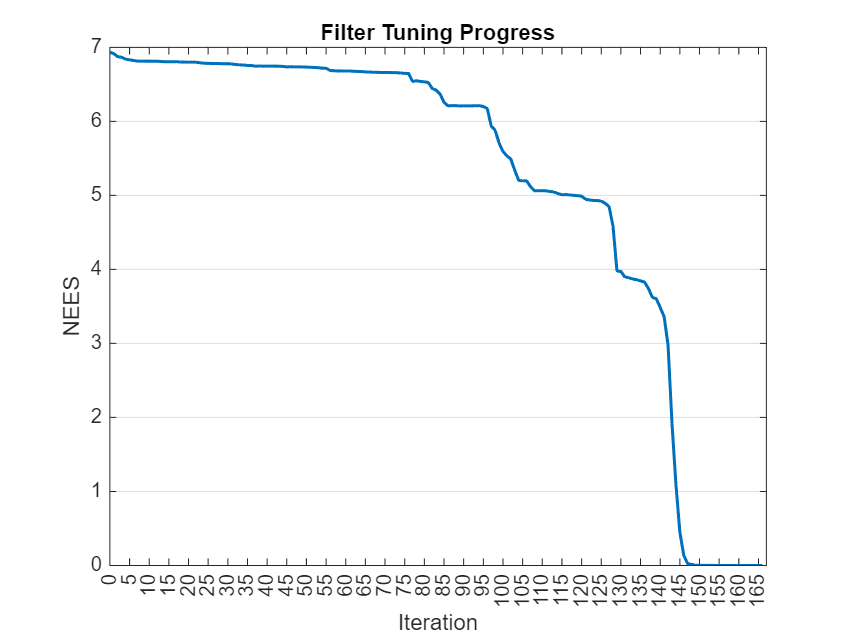


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


tunedProps = struct with fields:
       ProcessNoise: [4×4 double]
    StateCovariance: [7×7 double]


tunedProps = tune(tuner,objDet,truthTable)

Generate the filter initialization function after tuning by using the `exportToFunction` object function.

exportToFunction(tuner,"tunedInitFcn_CT")

Obtain the tuned filter by evaluating the tuned initialization function on an object detection. Show the tuned process noise.

tunedFilter = tunedInitFcn_CT(objDet{1})

tunedFilter =   trackingEKF with properties:

                          State: [7×1 double]
                StateCovariance: [7×7 double]

             StateTransitionFcn: @constturn
     StateTransitionJacobianFcn: @constturnjac
                   ProcessNoise: [4×4 double]
        HasAdditiveProcessNoise: 0

                 MeasurementFcn: @ctmeas
         MeasurementJacobianFcn: @ctmeasjac
         HasMeasurementWrapping: 1
               MeasurementNoise: [3×3 double]
    HasAdditiveMeasurementNoise: 1

                MaxNumOOSMSteps: 0

                EnableSmoothing: 0


tunedFilter.ProcessNoise

ans =     0.0025         0         0         0
         0    0.0025         0         0
         0         0    0.0001         0
         0         0         0    0.0025


posIdx = indices(1:3:end);
veloIdx = indices(2:3:end);
pos = tunedFilter.StateCovariance(posIdx)

pos = 1.0e+16 *

    1.0002    0.0000    0.0000


velo = tunedFilter.StateCovariance(veloIdx)

velo = 1.0e+08 *

    2.2317    0.0000


*Copyright 2022 The MathWorks, Inc.*